# Chapter 8 ATAP Exercises

## Convergence for Analytic Functions

#### Mason Mault June 2025

Exercises worked

Exercise 8.2: A Chebyshev series

Exercise 8.3: Interpolation of an entire function

Exercise 8.9: You can't judge smoothness by eye

**Exercise 8.2: A Chebyshev series**

Investigate the coefficients for $f\left(x\right)=\sin \left(100x-0\ldotp 1\right)+0\ldotp 01\tanh \left(20x\right)$

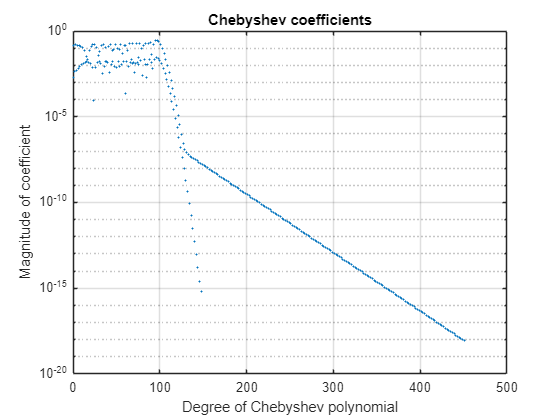

x = chebfun('x');
f = sin(100*x - 0.1) + 0.01 * tanh(20*x);

figure
plotcoeffs(f)

Plot the function to check for even, odd, or neither

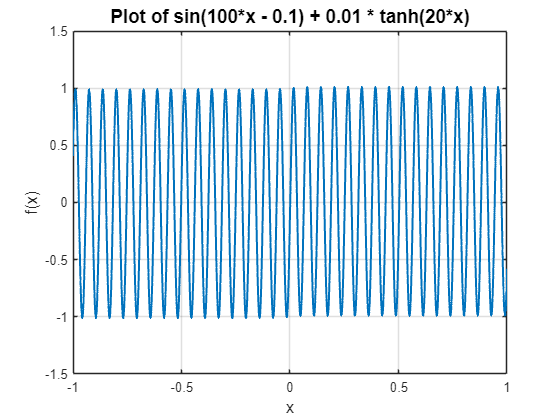

figure
plot(f, 'LineWidth', 1.5) 
grid on
title('Plot of sin(100*x - 0.1) + 0.01 * tanh(20*x)', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

The function is neither even nor odd, but based on the coefficient plot, the function is more even.

Throughout, the even coefficients are always smaller than the odd, with the even coefficients getting sent to 0 around n = 150. The odd coefficients take longer to decrease as they are more present in the function.

**Exercise 8.3: Interpolation of an entire function**

The function $g\left(x\right)=\exp \left(-x^2 \right)$ is analytic throughout the entire complex x-plane, so theorem 8.2 (bound of chebyshev approximation error) can be applied for any value of $\rho >1$.

Theorem 8.1 states if g(x) is analytic in [-1, 1] and analytically continuable to the open Bernstein ellipse $E_{\rho \;}$, where $|g\left(x\right)|\le M$for some M, then its Chebyshev coefficients satisfy |$a_0 |\le M$and


$$|a_k |\le 2M\rho^{-k} \;,k\ge 1$$


Theorem 8.2 says if g satisfies theorem 8.1, then for each $n\ge 0$ its Chebyshev projections satisfy


$$||g-g_n ||\le$$

$$\;\frac{{2M\rho }^{-n} }{\rho -1}$$


and its Chebyshev interpolants satisfy


$$||g-p_n ||\le$$

$$\;\frac{{4M\rho }^{-n} }{\rho -1}$$


Build a plot of $||g-p_n ||$  

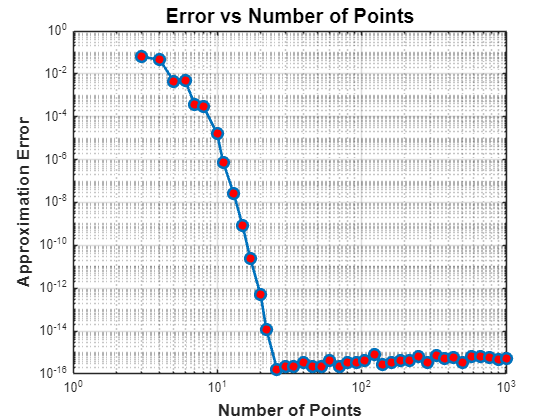

g = chebfun(exp(-x.^2));

% initialization 
list = round(2.^linspace(0, 10, 50));
err = zeros(length(list), 1);

% compute chebfun interpolation and error at each value of list
for j = 1:length(list)
    i = list(j);
    n = i - 1;
    pn = chebfun(g, i);
    % build and measure error on grid of 2n points
    x = chebpts(2*n);
    err(j) = norm(pn(x) - g(x), inf);
end

figure
loglog(list, err, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'Color', [0 0.4470 0.7410]);
grid on

xlabel('Number of Points', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Approximation Error', 'FontSize', 13, 'FontWeight', 'bold');
title('Error vs Number of Points', 'FontSize', 15, 'FontWeight', 'bold');

Now include the theoretical bounds for $\rho =1\ldotp 1,1\ldotp 2,1\ldotp 4,2,3,5,8$. 

First, draw the Berinstein ellipses

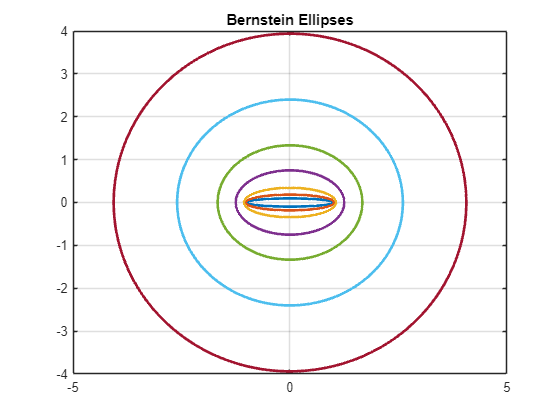

% initialize rhoList
rhoList = [1.1, 1.2, 1.4, 2, 3, 5, 8];

% initialize M list, used in theorem 8.2
MList = zeros(length(rhoList), 1);

% plot image of Bernstein ellipse in complex x plane of the circle of
% radius rho in the z-plane under the Joukowsky map (page 56 ATAP)
z = exp(2i*pi*x);

for j = 1:length(rhoList)
    rho = rhoList(j);
    % Bernstein ellipse 
    e = 0.5 * (rho*z + (1./(rho*z)));
    % |g(x)| <= M in the Bernstein ellipse
    MList(j) = max(abs(exp(-e.^2)));
    plot(real(e), imag(e), 'LineWidth', 2);
    hold on
end

title('Bernstein Ellipses');
grid on;

% initialize theoretical bound from eq 8.3
bound = zeros(length(7), 1);
   
% use theorem 8.2
for k = 1:length(rhoList)
    rho = rhoList(k);
    M = MList(k);
    
    for j = 1:length(list)
        n = list(j) - 1;
        bound(k, j) = (4 * M) / (rho^n * (rho - 1));
    end
end

Plot actual error with theoretical bounds

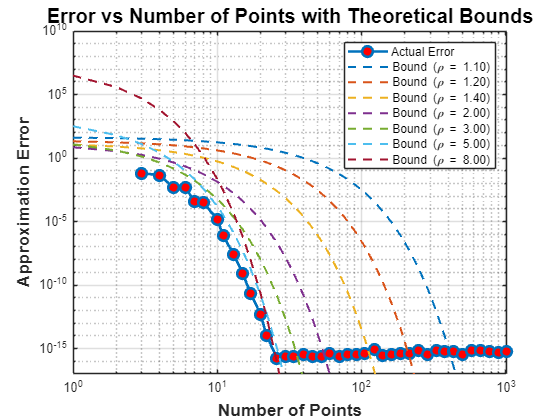

figure;
loglog(list, err, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 8, ...
    'MarkerFaceColor', 'r', ...
    'DisplayName', "Actual Error");
hold on;
grid on;

colors = lines(length(rhoList));
for k = 1:length(rhoList)
    loglog(list, bound(k, :), '--', ...
        'Color', colors(k,:), ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('Bound (\\rho = %.2f)', rhoList(k)));
end

xlabel('Number of Points', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Approximation Error', 'FontSize', 13, 'FontWeight', 'bold');
title('Error vs Number of Points with Theoretical Bounds', ...
    'FontSize', 15, 'FontWeight', 'bold');

legend show;
legend('Location', 'northeast');
ylim([1e-17, 1e10])

The slope of the data match the theoretical bounds very closely, with the error decaying to machine precision very rapidly.

**Exercise 8.9: You can't judge smoothness by eye**

Define $h\left(x\right)=2+\sin \left(50x\right)$ and $u\left(x\right)={h\left(x\right)}^{1\ldotp 0001}$and construct Chebfuns on [-1, 1]. Inspect their degrees.

h = chebfun(2 + sin(50*x));

length(h)

ans = 2046

u = h.^(1.0001);

length(u)

ans = 754

Explore the functions

max(h)

ans = 3.0000

max(u)

ans = 3.0003

Plot the functions 

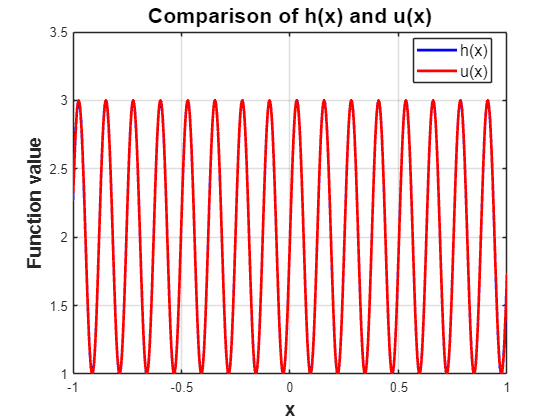

figure
plot(h, 'LineWidth', 2, 'Color', 'b');
hold on;   
plot(u, 'LineWidth', 2, 'Color', 'r'); 

xlabel('x', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Function value', 'FontSize', 14, 'FontWeight', 'bold');
title('Comparison of h(x) and u(x)', ...
    'FontSize', 16, 'FontWeight', 'bold');

legend({'h(x)', 'u(x)'}, 'FontSize', 12, 'Location', 'best');
grid on;

Compare Chebyshev coefficients 

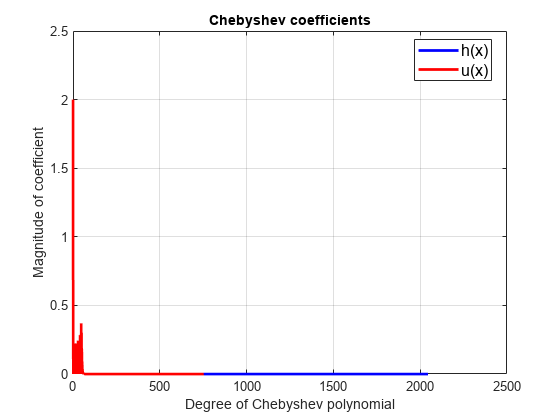

figure
hold on
plotcoeffs(h, 'b', 'LineWidth', 2);
plotcoeffs(u, 'r', 'LineWidth', 2);
legend({'h(x)', 'u(x)'}, 'FontSize', 12, 'Location', 'best');
grid on;
box on;